# Mach band illusion

The Mach band illusion is a classic phenomenon of visual perception. At the boundaries between gray bands with gradual changes in luminance, the human eye perceives regions near the edges as being brighter or darker than their actual luminance.

Specifically, near the junction of a light and a dark gray band, the lighter side appears even brighter, while the darker side appears even darker.

## Create the visual input for the Mach Band Illusion.

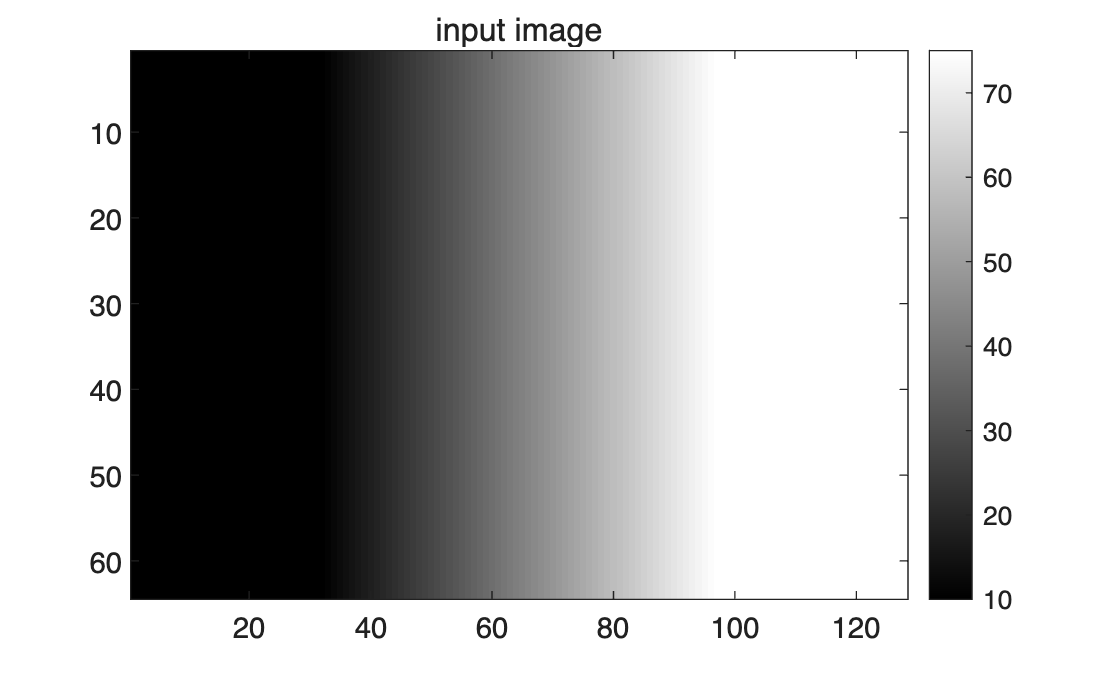

clear all; clc;

matrix = zeros(64, 128);
matrix(:, 1:32) = 10;
for i = 1:65
    matrix(:, 32+i) = 10+i;
end
matrix(find(matrix == 0)) = 75;

% plot figure
figure;
imagesc(matrix);
colormap('gray');
axis off;
title('input image');
colorbar;

### At the transition from the ramp to the white area, you should see a brighter vertical bar. At the transition from the ramp to the black area, you should see a darker vertical bar.

## Plot brightness as a function of horizontal position.

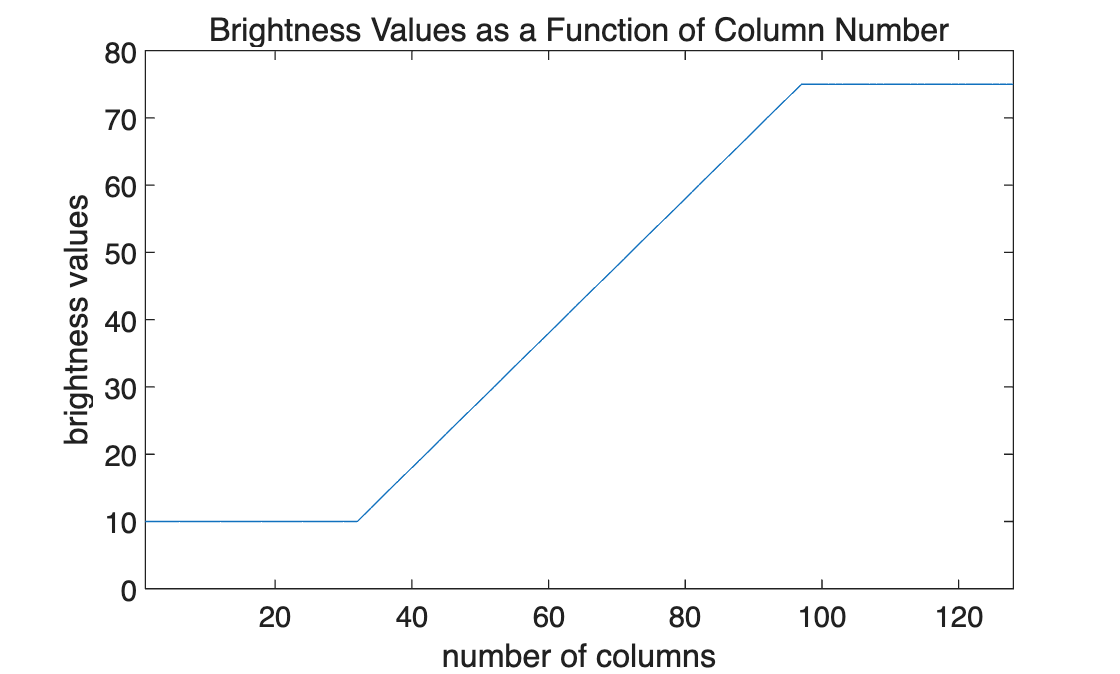

figure;
plot(matrix(1,:))
axis tight;
ylim([0 80]);
title('Brightness Values as a Function of Column Number');
xlabel('number of columns');
ylabel('brightness values');

### This shows the horizontal variation in color (luminance) of the visual input image. The changes in color are smooth and continuous.

## Create the receptive field of a retinal ganglion cell.

The center-surround antagonistic receptive field can be described using a 2D difference of Gaussians.

The center of the receptive field is modeled by a narrower 2D Gaussian function with a smaller variance, representing the excitatory region.

The surround is modeled by a broader 2D Gaussian function with a larger variance, representing the inhibitory region.

That is:

Center：$G_e \left(x,y\right)=\frac{1}{2\pi {\sigma_e }^2 }*e^{-\frac{1}{2{\sigma_e }^2 }\left(x^2 +y^2 \right)}$

Surround：$G_i \left(x,y\right)=\frac{1}{2\pi {\sigma_i }^2 }*e^{-\frac{1}{2{\sigma_i }^2 }\left(x^2 +y^2 \right)}$

Where $\sigma_e <\sigma_i$

By weighting the two Gaussians with a certain ratio and taking their difference, the complete receptive field can be described as follows:


$$\left.{\mathrm{RF}\left(x,y\right)=S*\left\lbrack G\right.}_e \left(x,y\right)-\mathrm{IE}*G_i \left(x,y\right)\right\rbrack$$


Where S is the overall strength of the field’s connectivity; IE is the ratio of inhibition to excitation.

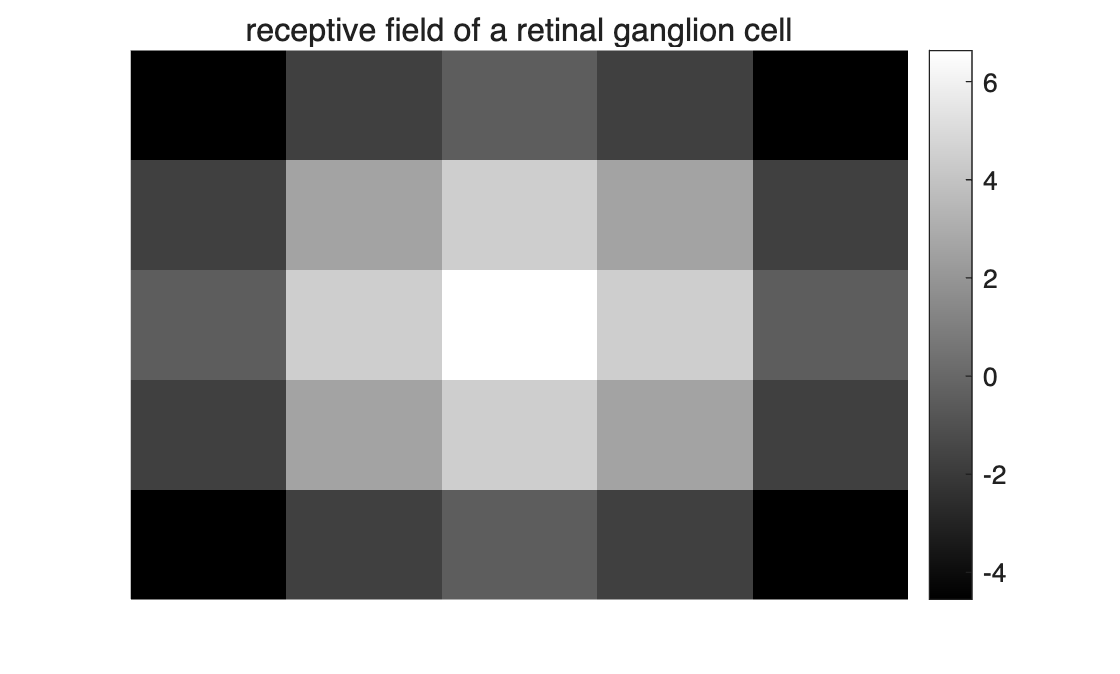

x = -2:1:2;
[X, Y] = meshgrid(x);
R = sqrt(X.^2 + Y.^2);
sigma_center = 2;
sigma_surround = 6;
Excitetory_center = 1/(2*pi*sigma_center^2) * (exp(-(R.^2)/(2*sigma_center^2)));
Inhibitory_surround = 1/(2*pi*sigma_surround^2) * (exp(-(R.^2) / (2*sigma_surround^2)));

%S*(Egaus – IE*Igaus) 
S = 500;    %the overall strength of the field's connectivity
IE = 6;     %the ratio of inhibition to excitation
receptive_field = S*(Excitetory_center - IE*Inhibitory_surround);

%plot figure
figure;
imagesc(receptive_field);
colormap('gray');
colorbar;
axis off;
title('receptive field of a retinal ganglion cell');

## Convolve your receptive field and input image.

By applying convolution, we can compute the preliminary processing result of the input image by all activated retinal ganglion cells.

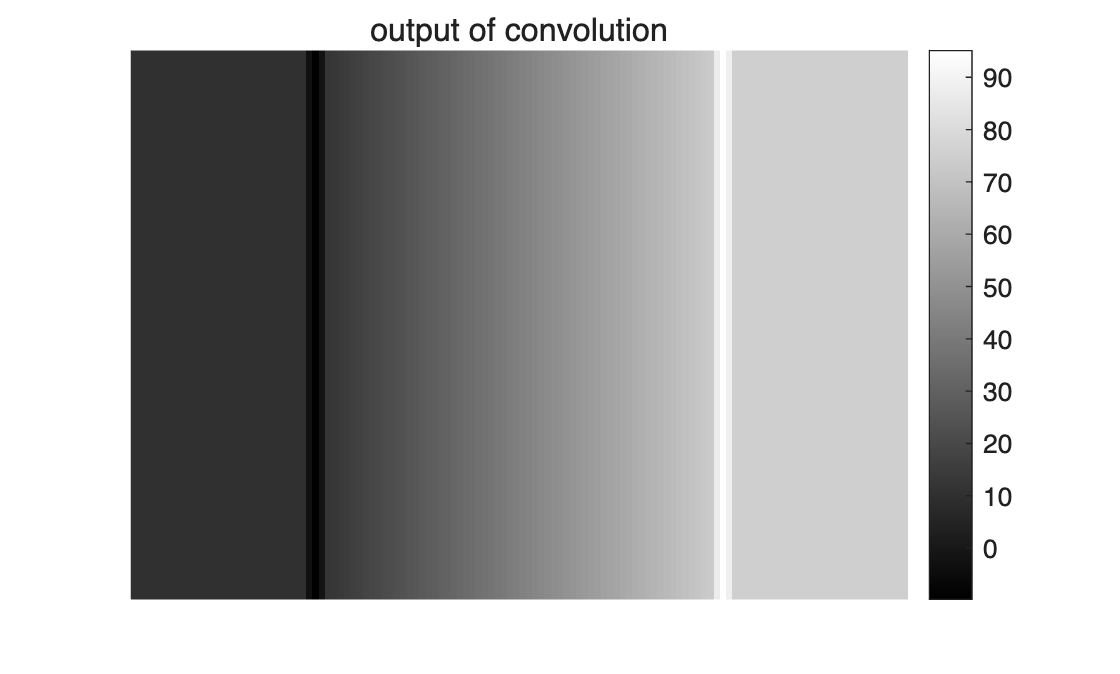

matrix_conv = conv2(matrix,receptive_field,'valid');

%plot figure
figure;
imagesc(matrix_conv);
colormap('gray');
colorbar;
axis off;
title('output of convolution');

### After preliminary processing by the retinal ganglion cells, two distinct bands appear in the input image.

## Plot brightness as a function of horizontal position again.

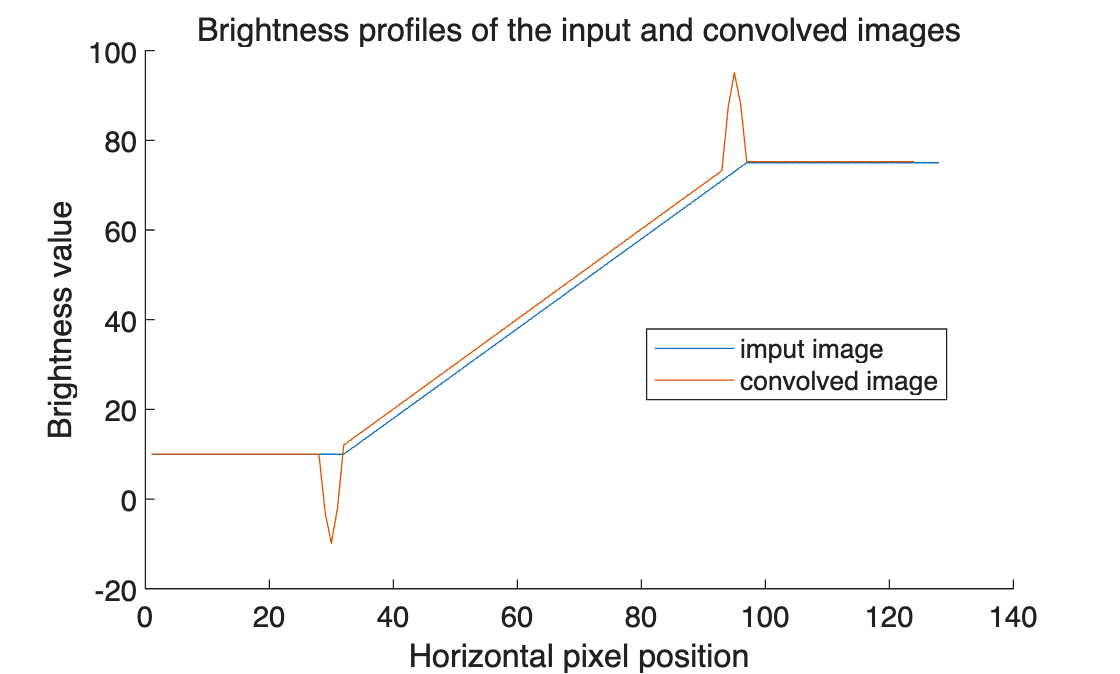

figure;
hold on;
plot(matrix(1,:));
plot(matrix_conv(1,:));
hold off;
xlabel('Horizontal pixel position');
ylabel('Brightness value');
title('Brightness profiles of the input and convolved images');
legend('imput image', 'convolved image','Location','best');

### After processing by the retinal ganglion cells, there is an abrupt color change at the boundary where color transitions occur in the image

## Conclusion

The Mach Band illusion in the plots arises from the enhanced contrast at luminance edges after convolving the input with a center-surround receptive field model. This illusion occurs at the retinal due to the antagonistic center-surround organization of receptive fields. It reveals a desirable property of the visual system—emphasizing edges to efficiently and robustly represent visual scenes.